# Machine Learning Online Class

## =============== Part 1: Loading movie ratings dataset ================

fprintf('Loading movie ratings dataset.\n\n');

Loading movie ratings dataset.




%  Load data
load ('ex8_movies.mat');

%  Y is a 1682x943 matrix, containing ratings (1-5) of 1682 movies on 
%  943 users
%
%  R is a 1682x943 matrix, where R(i,j) = 1 if and only if user j gave a
%  rating to movie i

%  From the matrix, we can compute statistics like average rating.
fprintf('Average rating for movie 1 (Toy Story): %f / 5\n\n', ...
        mean(Y(1, R(1, :))));

Average rating for movie 1 (Toy Story): 3.878319 / 5



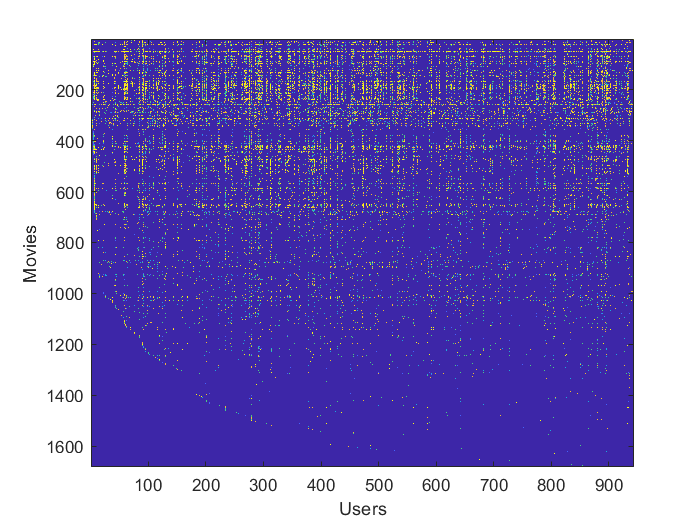


%  We can "visualize" the ratings matrix by plotting it with imagesc
imagesc(Y);
ylabel('Movies');
xlabel('Users');


% fprintf('\nProgram paused. Press enter to continue.\n');
% pause;

## ============ Part 2: Collaborative Filtering Cost Function ===========

%  Load pre-trained weights (X, Theta, num_users, num_movies, num_features)
load ('ex8_movieParams.mat');

%  Reduce the data set size so that this runs faster
num_users = 4; num_movies = 5; num_features = 3;
X = X(1:num_movies, 1:num_features);
Theta = Theta(1:num_users, 1:num_features);
Y = Y(1:num_movies, 1:num_users);
R = R(1:num_movies, 1:num_users);

%  Evaluate cost function
J = cofiCostFunc([X(:) ; Theta(:)], Y, R, num_users, num_movies, ...
               num_features, 0);
           
fprintf(['Cost at loaded parameters: %f '...
         '\n(this value should be about 22.22)\n'], J);

Cost at loaded parameters: 22.224604 
(this value should be about 22.22)



% fprintf('\nProgram paused. Press enter to continue.\n');
% pause;

## ============== Part 3: Collaborative Filtering Gradient ==============

fprintf('\nChecking Gradients (without regularization) ... \n');


Checking Gradients (without regularization) ... 



%  Check gradients by running checkNNGradients
checkCostFunction;

    0.9845    0.9845
   -1.2717   -1.2717
   -1.7052   -1.7052
         0         0
   -3.7928   -3.7928
    1.9492    1.9492
    1.3028    1.3028
         0         0
   -4.7722   -4.7722
    0.9211    0.9211
    1.1007    1.1007
         0         0
    1.3446    1.3446
    1.2473    1.2473
    0.8016    0.8016
    0.9625    0.9625
    0.9625    0.9625
    0.2862    0.2862
   -0.4118   -0.4118
   -0.6227   -0.6227
   -0.3178   -0.3178
   -1.4399   -1.4399
    0.6779    0.6779
   -3.1014   -3.1014
   -2.1479   -2.1479
   -2.3931   -2.3931
   -2.4436   -2.4436

The above two columns you get should be very similar.
(Left-Your Numerical Gradient, Right-Analytical Gradient)

If your cost function implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 1.11346e-12



% fprintf('\nProgram paused. Press enter to continue.\n');
% pause;

## ========= Part 4: Collaborative Filtering Cost Regularization ========

%  Evaluate cost function
J = cofiCostFunc([X(:) ; Theta(:)], Y, R, num_users, num_movies, ...
               num_features, 1.5);
           
fprintf(['Cost at loaded parameters (lambda = 1.5): %f '...
         '\n(this value should be about 31.34)\n'], J);

Cost at loaded parameters (lambda = 1.5): 31.344056 
(this value should be about 31.34)


% 
% fprintf('\nProgram paused. Press enter to continue.\n');
% pause;

## ======= Part 5: Collaborative Filtering Gradient Regularization ======

%  
fprintf('\nChecking Gradients (with regularization) ... \n');


Checking Gradients (with regularization) ... 



%  Check gradients by running checkNNGradients
checkCostFunction(1.5);

    3.4242    3.4242
    6.1585    6.1585
    1.2582    1.2582
    1.9691    1.9691
    1.2582    1.2582
    2.1379    2.1379
   -0.3135   -0.3135
    5.4827    5.4827
    2.6294    2.6294
    2.0589    2.0589
    1.8886    1.8886
    2.9244    2.9244
   -4.5459   -4.5459
   -0.6346   -0.6346
   -0.6762   -0.6762
   -0.8616   -0.8616
    5.1261    5.1261
   -2.7808   -2.7808
   -0.8750   -0.8750
   -2.4140   -2.4140
   -2.6094   -2.6094
    0.6716    0.6716
   -1.0020   -1.0020
    2.2311    2.2311
   -0.8498   -0.8498
   -2.6674   -2.6674
    2.9236    2.9236

The above two columns you get should be very similar.
(Left-Your Numerical Gradient, Right-Analytical Gradient)

If your cost function implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 2.16976e-12



% fprintf('\nProgram paused. Press enter to continue.\n');
% pause;

## ============== Part 6: Entering ratings for a new user ===============

movieList = loadMovieList();

%  Initialize my ratings
my_ratings = zeros(1682, 1);

% Check the file movie_idx.txt for id of each movie in our dataset
% For example, Toy Story (1995) has ID 1, so to rate it "4", you can set
my_ratings(1) = 4;

% Or suppose did not enjoy Silence of the Lambs (1991), you can set
my_ratings(257) = 2;

% We have selected a few movies we liked / did not like and the ratings we
% gave are as follows:
my_ratings(71) = 3;
my_ratings(94)= 4;
my_ratings(95) = 2;
my_ratings(98)= 5;
my_ratings(501)= 4;
my_ratings(1316) = 4;
my_ratings(1060) = 3;
my_ratings(313) = 5;
my_ratings(99)= 1;

fprintf('\n\nNew user ratings:\n');



New user ratings:


for i = 1:length(my_ratings)
    if my_ratings(i) > 0 
        fprintf('Rated %d for %s\n', my_ratings(i), ...
                 movieList{i});
    end
end

Rated 4 for Toy Story (1995)
Rated 3 for Lion King, The (1994)
Rated 4 for Home Alone (1990)
Rated 2 for Aladdin (1992)
Rated 5 for Silence of the Lambs, The (1991)
Rated 1 for Snow White and the Seven Dwarfs (1937)
Rated 2 for Men in Black (1997)
Rated 5 for Titanic (1997)
Rated 4 for Dumbo (1941)
Rated 3 for Adventures of Pinocchio, The (1996)
Rated 4 for Horse Whisperer, The (1998)



% fprintf('\nProgram paused. Press enter to continue.\n');
% pause;

## ================== Part 7: Learning Movie Ratings ====================

fprintf('\nTraining collaborative filtering...\n');


Training collaborative filtering...



%  Load data
load('ex8_movies.mat');

%  Y is a 1682x943 matrix, containing ratings (1-5) of 1682 movies by 
%  943 users
%
%  R is a 1682x943 matrix, where R(i,j) = 1 if and only if user j gave a
%  rating to movie i

%  Add our own ratings to the data matrix
Y = [my_ratings Y];
R = [(my_ratings ~= 0) R];

%  Normalize Ratings
[Ynorm, Ymean] = normalizeRatings(Y, R);

%  Useful Values
num_users = size(Y, 2);
num_movies = size(Y, 1);
num_features = 10;

% Set Initial Parameters (Theta, X)
X = randn(num_movies, num_features);
Theta = randn(num_users, num_features);

initial_parameters = [X(:); Theta(:)];

% Set options for fmincg
options = optimset('GradObj', 'on', 'MaxIter', 100);

% Set Regularization
lambda = 10;
theta = fmincg (@(t)(cofiCostFunc(t, Ynorm, R, num_users, num_movies, ...
                                num_features, lambda)), ...
                initial_parameters, options);

Iteration     1 | Cost: 3.190645e+05
Iteration     2 | Cost: 1.257605e+05
Iteration     3 | Cost: 1.026069e+05
Iteration     4 | Cost: 7.985918e+04
Iteration     5 | Cost: 5.918076e+04
Iteration     6 | Cost: 5.137147e+04
Iteration     7 | Cost: 4.725994e+04
Iteration     8 | Cost: 4.462380e+04
Iteration     9 | Cost: 4.315057e+04
Iteration    10 | Cost: 4.262179e+04
Iteration    11 | Cost: 4.157846e+04
Iteration    12 | Cost: 4.091178e+04
Iteration    13 | Cost: 4.045764e+04
Iteration    14 | Cost: 4.018128e+04
Iteration    15 | Cost: 4.012322e+04
Iteration    16 | Cost: 3.992893e+04
Iteration    17 | Cost: 3.976498e+04
Iteration    18 | Cost: 3.970092e+04
Iteration    19 | Cost: 3.956530e+04
Iteration    20 | Cost: 3.949141e+04
Iteration    21 | Cost: 3.942861e+04
Iteration    22 | Cost: 3.937177e+04
Iteration    23 | Cost: 3.933426e+04
Iteration    24 | Cost: 3.928881e+04
Iteration    25 | Cost: 3.925591e+04
Iteration    26 | Cost: 3.923417e+04
Iteration    27 | Cost: 3.920052e+04
I


% Unfold the returned theta back into U and W
X = reshape(theta(1:num_movies*num_features), num_movies, num_features);
Theta = reshape(theta(num_movies*num_features+1:end), ...
                num_users, num_features);

fprintf('Recommender system learning completed.\n');

Recommender system learning completed.



% fprintf('\nProgram paused. Press enter to continue.\n');
% pause;

## ================== Part 8: Recommendation for you ====================

p = X * Theta';
my_predictions = p(:,1) + Ymean;

movieList = loadMovieList();

[r, ix] = sort(my_predictions, 'descend');
fprintf('\nTop recommendations for you:\n');


Top recommendations for you:


for i=1:10
    j = ix(i);
    fprintf('Predicting rating %.1f for movie %s\n', my_predictions(j), ...
            movieList{j});
end

Predicting rating 5.0 for movie Great Day in Harlem, A (1994)
Predicting rating 5.0 for movie Saint of Fort Washington, The (1993)
Predicting rating 5.0 for movie They Made Me a Criminal (1939)
Predicting rating 5.0 for movie Star Kid (1997)
Predicting rating 5.0 for movie Prefontaine (1997)
Predicting rating 5.0 for movie Someone Else's America (1995)
Predicting rating 5.0 for movie Entertaining Angels: The Dorothy Day Story (1996)
Predicting rating 5.0 for movie Santa with Muscles (1996)
Predicting rating 5.0 for movie Marlene Dietrich: Shadow and Light (1996)
Predicting rating 5.0 for movie Aiqing wansui (1994)



fprintf('\n\nOriginal ratings provided:\n');



Original ratings provided:


for i = 1:length(my_ratings)
    if my_ratings(i) > 0 
        fprintf('Rated %d for %s\n', my_ratings(i), ...
                 movieList{i});
    end
end

Rated 4 for Toy Story (1995)
Rated 3 for Lion King, The (1994)
Rated 4 for Home Alone (1990)
Rated 2 for Aladdin (1992)
Rated 5 for Silence of the Lambs, The (1991)
Rated 1 for Snow White and the Seven Dwarfs (1937)
Rated 2 for Men in Black (1997)
Rated 5 for Titanic (1997)
Rated 4 for Dumbo (1941)
Rated 3 for Adventures of Pinocchio, The (1996)
Rated 4 for Horse Whisperer, The (1998)
